% cd('/Users/sushant/Desktop/ITC/JIPITE')
% 
% %% Step 0: Load and Prepare Data
% filename = 'vibrationforanalysis.xlsx';
% data = readtable(filename);
% data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
% data = data(data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0, :);  % Remove pump-off
% data.DateTime = datetime(data.DateTime);
% 
% %% Step 1: Feature Engineering
% features = table;
% features.XRMS = data.X_RMS;
% features.YRMS = data.Y_RMS;
% features.ZRMS = data.Z_RMS;
% features.XRMS_Trend = data.XRMS_Trend;
% features.YRMS_Trend = data.YRMS_Trend;
% features.ZRMS_Trend = data.ZRMS_Trend;
% features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
% features.dXRMS = [NaN; diff(data.X_RMS)];
% features.dYRMS = [NaN; diff(data.Y_RMS)];
% features.dZRMS = [NaN; diff(data.Z_RMS)];
% 
% features = features(2:end, :);
% timestamps = data.DateTime(2:end);
% 
% %% Step 2: Normalize
% X = normalize(features{:,:}, 'range');
% 
% %% Step 3: Train-Test Split
% % Assume first 200 are healthy
% XTrain = X(1:200, :);
% XAll   = X;
% 
% %% ========== MODEL 1: Isolation Forest ==========
% mdlIF = iforest(XTrain, 'NumLearners', 100, 'ContaminationFraction', 0.01);
% [isAnomalyIF, scoresIF] = predict(mdlIF, XAll);
% 
% %% ========== MODEL 2: One-Class SVM ==========
% mdlSVM = fitcsvm(XTrain, ones(size(XTrain,1),1), ...
%     'KernelScale','auto', ...
%     'Standardize', true, ...
%     'OutlierFraction', 0.01);  % Similar to ContaminationFraction
% 
% [labelSVM, scoreSVM] = predict(mdlSVM, XAll);
% % Anomalies are where label = -1
% isAnomalySVM = labelSVM == -1;
% scoresSVM = -scoreSVM(:,2);  % Flip to match "anomaly score" style
% 
% %% ========== MODEL 3: Mahalanobis Distance ==========
% mu = mean(XTrain);
% Sigma = cov(XTrain);
% mahalDist = mahal(XAll, XTrain);  % Classic outlier detection
% % Use chi-squared 95% threshold with df = num features
% thresholdMahal = chi2inv(0.95, size(XTrain,2));
% isAnomalyMahal = mahalDist > thresholdMahal;
% 
% %% ========== Visualization ==========
% figure;
% subplot(3,1,1)
% plot(timestamps, scoresIF, 'b');
% yline(0.5, '--r', 'Threshold');
% title('Anomaly Score - Isolation Forest');
% ylabel('Score'); grid on;
% 
% subplot(3,1,2)
% plot(timestamps, scoresSVM, 'g');
% title('Anomaly Score - One-Class SVM');
% ylabel('Score'); grid on;
% 
% subplot(3,1,3)
% plot(timestamps, mahalDist, 'k');
% yline(thresholdMahal, '--r', '95% Limit');
% title('Mahalanobis Distance');
% ylabel('Score'); grid on;
% 
% xlabel('Time');
% 
% %% Optional: Mark known anomaly time
% xline(datetime('2025-02-15 12:39:13'), '--m', 'Known Fault');

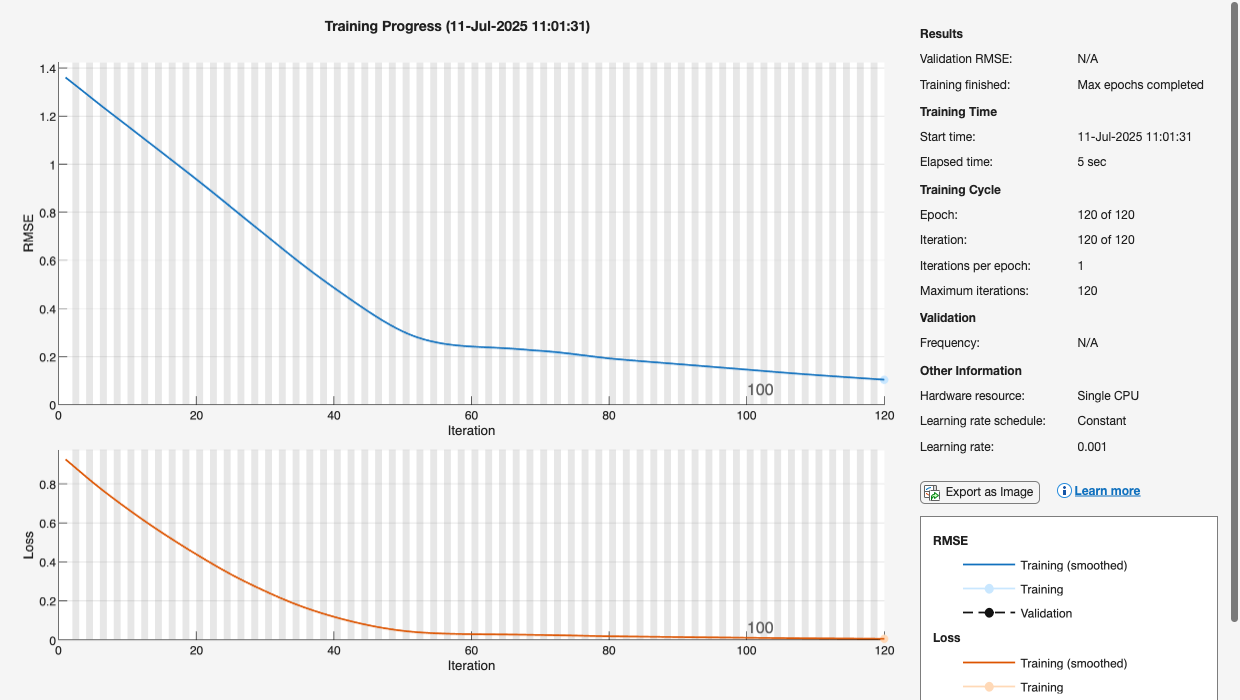


cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'vibrationforanalysis.xlsx';  % replace with actual file
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);

features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];
features = rmmissing(features);  % remove NaNs

X = normalize(features{:,:}, 'range');



numTrain = floor(0.7 * size(X, 1));

XTrain = {X(1:round(0.7 * end), :)'};  
Xseq   = {X'};                         


layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);


net = trainNetwork(XTrain, XTrain, layers, options);

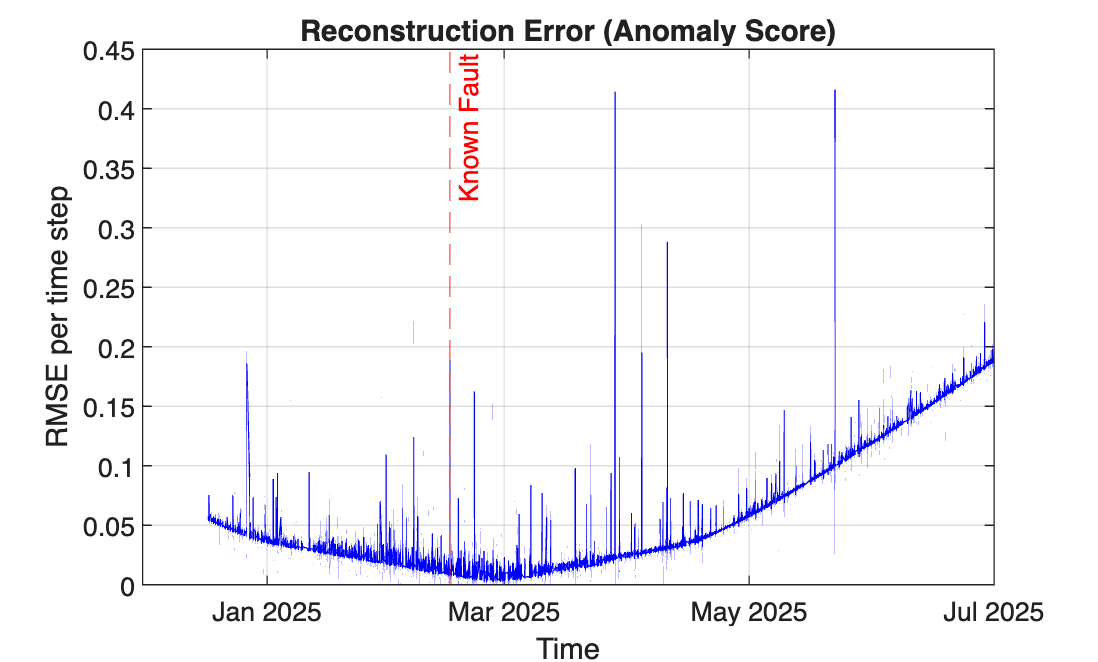



Ypred = predict(net, Xseq);


reconLoss = sqrt(mean((Xseq{1} - Ypred{1}).^2, 1));  

timestamps = data.DateTime(end - numel(reconLoss) + 1:end);

figure;
plot(timestamps, reconLoss, 'b');
title('Reconstruction Error (Anomaly Score)');
ylabel('RMSE per time step');
xlabel('Time');
grid on;


 xline(datetime('2025-02-15 12:39:13'), '--r', 'Known Fault')